# Compile Figures for Synthetic Data

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'Synthetic/';

%What is the original data?
originaldata = {'syn_synthesized_data.txt'};

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfigures = '~/Documents/git_Research/Permafrost_ERRA/Permafrost_ERRA/figures/';

%Where is your data?
workdir = '~/Documents/git_Research/Permafrost_ERRA/Permafrost_ERRA/datERRA/Synthetic';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Lets plot the results

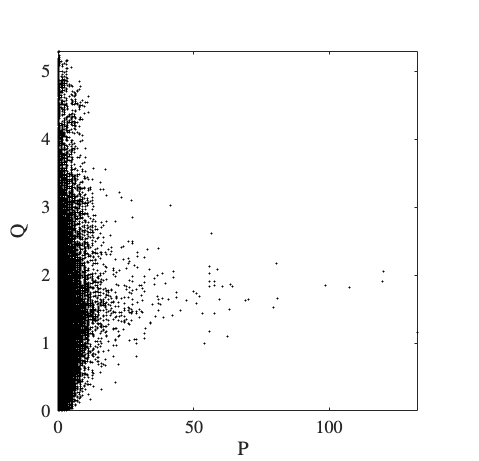

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 6.6500 6.4000]
       Units: 'inches'

  Show all properties


% % %Plot time with discharge and precipitation. This function will change
% % %depending on data format. Please change this function accordingly
% % origdat=char(strcat(originaldata(1)));
% % f1 = figtQP_plot_UK(origdat,workdir,workdirfig,printfig)

%Plot P and Q as scatter. We use data from ERRA so this is standardized
f2 = figPQ_scatter(workdir,workdirfig,printfig,2)

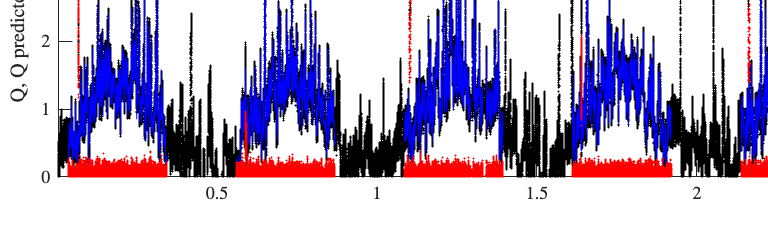

f3 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6500 6.4000]
       Units: 'inches'

  Show all properties



%Plot ERRA time with real discharge, predicted discharge, and its residual
f3 = figtQQp_plot(workdir,workdirfig,printfig,2)

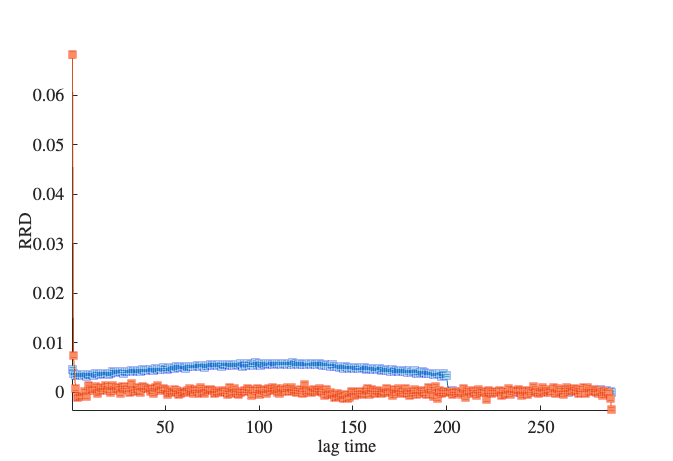

f4 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 9.3500 6.4000]
       Units: 'inches'

  Show all properties



%Plot lagtime with RRD
f4 = figtRRD_plot(workdir,workdirfig,printfig,2)